clc;clear;

## Set derivative gain

g0 = 1;
g1 = 0.1;
h = 1;

## Prepare fuzzy controller

generate_pendulum_ctrl_triangular;

## Visualize fuzzy controller

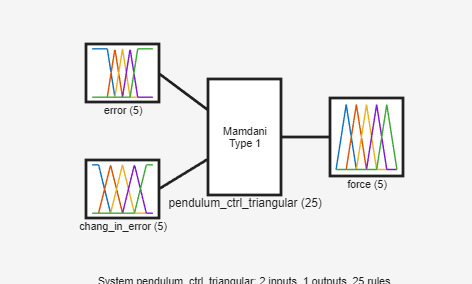

% plot block diagram
plotfis(pendulum_ctrl_triangular);
theme("light");
exportgraphics(gcf,"figures/plotfis.svg");

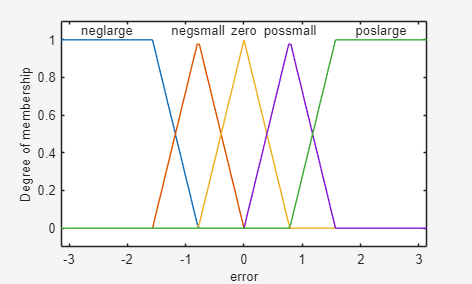


% plot member function
plotmf(pendulum_ctrl_triangular,"input",1);
theme("light");
exportgraphics(gcf,"figures/plotmf_error.svg",Units="inches",width=5,height=3);

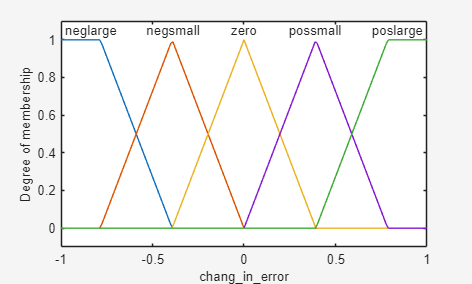


plotmf(pendulum_ctrl_triangular,"input",2);
theme("light");
exportgraphics(gcf,"figures/plotmf_change_in_error.svg",Units="inches",width=5,height=3);

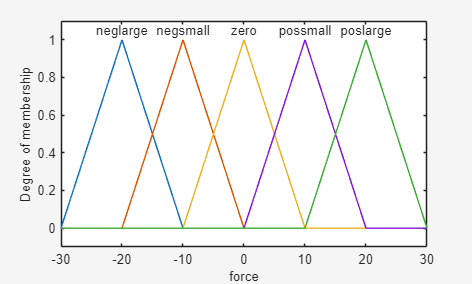


plotmf(pendulum_ctrl_triangular,"output",1);
theme("light");
exportgraphics(gcf,"figures/plotmf_force.svg",Units="inches",width=5,height=3);

## Start Simulink

% open_system("pendulum_system");
out=sim("pendulum_system");

## Plot

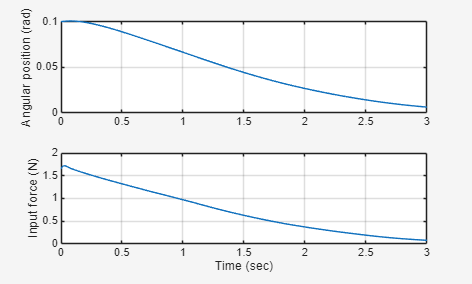

y_data = out.ScopeData.get("y").Values.Data(:,1);
y_time = out.ScopeData.get("y").Values.Time;
u_data = out.ScopeData.get("u").Values.Data(:,1);
u_time = out.ScopeData.get("u").Values.Time;

tiledlayout("vertical")
nexttile
plot(y_time,y_data,"DisplayName","y_data");
ylabel("Angular position (rad)");
legend off;
grid on;

nexttile
plot(u_time,u_data,"DisplayName","u_data");
xlabel("Time (sec)");
ylabel("Input force (N)");
legend off;
grid on;
theme("light");

exportgraphics(gcf,"figures/plot.svg",Units="inches",width=8,height=6);